# Using Bode diagrams to assess the impact of delays on closed-loop behaviour

The main purpose of this file is to explore the impact of delay on closed-loop performance, as compared to the same system with no delay. The main focus is insights gained from the Bode diagrams and thus gain and phase margins. It will be seen that in general, the compensator design should be done with knowledge of the delay as otherwise the compensator may be inappropriate.

The script assumes that students have gone through lag, lead and lead-lag design (**lead_design_with_bode.mlx,lead_lag_design_with_bode.mlx and lag_design_with_bode.mlx). **

This file takes those files as given and considers the impact on performance if a small delay is added to the system dynamics; the delay could be due to slow measurement or slow actuation.

This live script needs the control toolbox. Once profficient, students will probably find that the methods used in this script are mostly performed using sisotool. 

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Typical examples: Design performed assuming no delay

- Design taking account of the delay using lag compensation

## 1. Technical and mathematical background

This script assumes the following block diagram with system G(s) and compensator M(s). 

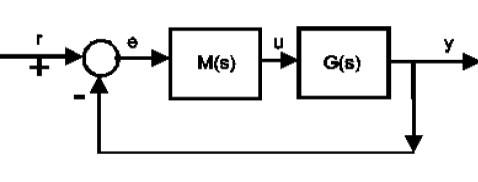

Adding a delay $\tau \;$to the system has, in effect, the following change:


$$G\left(s\right)\longrightarrow G\left(s\right)e^{-s\tau }$$


The gain does not change, but there is a noticeable change in phase:


$$\angle G\left(j\omega \right)e^{-j\omega \tau } =\angle G\left(j\omega \right)-\omega \tau$$


So the phase is more negative, and increasingly so for larger frequencies. Therefore, as the gain cross-over frequency does not change, we expect a loss in PM of $\omega \tau$ where $\omega$ is the gain cross-over frequency.  Clearly if $\omega \tau$ is signfiicant, for example greater than 5 degrees, this is a noticeable change and will have significant impact on damping and possibly convergence times.

Look at the Bode diagrams here which show how phase becomes more negative as the delay increases.

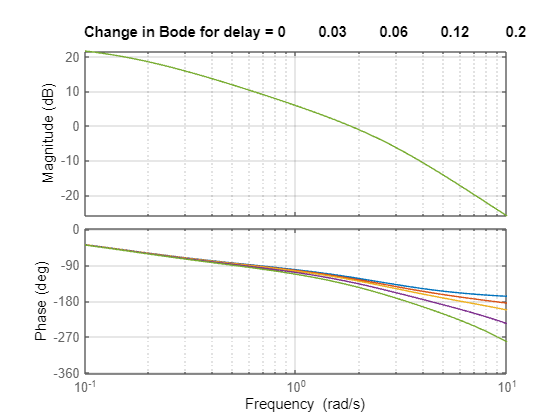

G=tf([1 3],[1 5 8 1]);
M=5;
delay=[0 0.03,0.06,0.12,0.2];
ndelay = length(delay);
Gdelay=cell(1,ndelay);
figure; clf
for k=1:ndelay
    Gdelay{k} = G*tf(1,1,'iodelay',delay(k));
    bode(Gdelay{k}*M,{0.1,10}); hold on; grid on 
end
title(['Change in Bode for delay = ',num2str(delay)])

**Change in phase margin**

The cross-over frequency is 1.8 rad/s . One can clearly see that the PM changes by $\omega \tau$.

disp('Phase margin with different delays')

Phase margin with different delays


[gm,pm,wp,wg] = margin(G*M);
disp('Cross-over frequency')

Cross-over frequency


w=wg

w = 1.8035

for k=1:ndelay
    
    [gm,pm,wp,wg] = margin(Gdelay{k}*M);
    disp(['Delay = ',num2str(delay(k)),', wT(deg) = ',num2str(w*delay(k)*180/pi),', PM = ',num2str(pm)])
   
end

Delay = 0, wT(deg) = 0, PM = 60.3026
Delay = 0.03, wT(deg) = 3.1001, PM = 57.2025
Delay = 0.06, wT(deg) = 6.2001, PM = 54.1025
Delay = 0.12, wT(deg) = 12.4002, PM = 47.9024
Delay = 0.2, wT(deg) = 20.6671, PM = 39.6355


disp('END of SECTION 1')

BELOW is SECTION 2: The impact of delay on margins and behaviour


#### Lead, lead-lag and lag compensator design 

Given the impact of delay on margins, it would be reasonable to take the delay into account when doing the compensator design.

- For a reminder on the design principles, please see the earlier files: **lead_design_with_bode.mlx, lead_lag_design_with_bode.mlx and lag_design_with_bode.mlx.**  

- In section 3 of this file an example is given of how those designs are impacted if the delay is known in advance but initially in section 2 we take the designs as being done with the assumption that there is no delay.

## 2. Typical examples: Design performed assuming no delay

This section assumes some reasonable compensator designs have been performed on the delay free system and then illustrates the impact of delay on the  closed-loop behaviour. The plots have fixed domains to improve messaging so if you change the systems to selections of your own, you may need to change these domains.

**System 1 lag and lead-lag compensator**. Comment out lines below to select desired compensator.

disp('BELOW is SECTION 2: The impact of delay on margins and behaviour')

G1=tf(1,[1 5 8 0]);
delay1=[0 0.1,0.2,0.4];
desiredPM = 60;
eramp=0.2;
%M1 = tf([7.2,.6],[1 0.015]);  % LAG ONLY
M1 = tf([43,44],[1 4])*tf([1 0.2],[1 0.04]); % LEAD LAG

**System 2 lag specification for step offset and compensator**

G2=tf(1,[1 5 8]);
delay2=[0 0.02,0.05,0.1];
desiredPM = 60;
ess=0.05;
M2=tf([25.6,11.5],[1,0.076]); %LAG

### 2.1 Bode and margins with and without delay

By drawing a vertical line at the gain cross-over frequency (0dB) which does not change, the user will note how the phase margin gets rapidly worse with growing delay. Comment out lines below to get desired system.

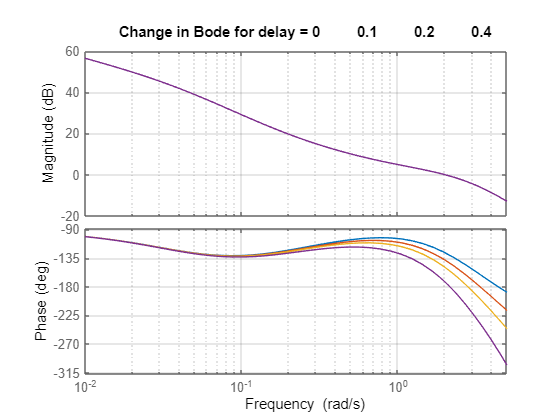

G=G1; M=M1;delay=delay1;
%G=G2; M=M2;delay=delay2;

figure;clf
ndelay = length(delay);
Gdelay=cell(1,ndelay);
for k=1:ndelay
    Gdelay{k} = G*tf(1,1,'iodelay',delay(k));
    bode(Gdelay{k}*M,{0.01,5}); hold on; grid on 
    [gm(k),pm(k)] = margin(Gdelay{k}*M);
end
title(['Change in Bode for delay = ',num2str(delay)])

disp(['Phase margin changes with delay: PM =  ',num2str(pm)])

Phase margin changes with delay: PM =  53.1652      41.6195      30.0739      6.98272     -4.56289


### 2.2 Step responses

The colour scheme for these plots matches those from the Bode diagram. From this it is clear that as the PM gets smaller, the overshoot and damping gets worse.

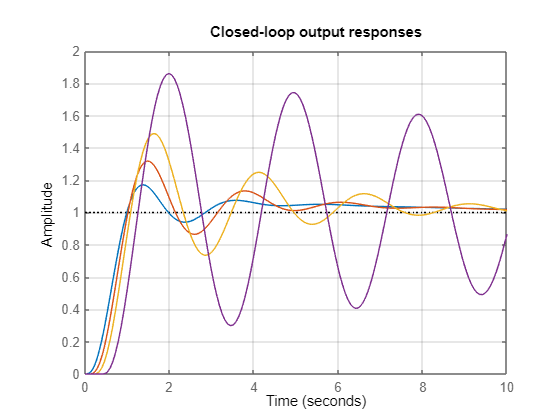

figure;clf
Gc = cell(1); Gcu=cell(1);
for k=1:ndelay
    Gc{k} = feedback(Gdelay{k}*M,1);
    Gcu{k} = feedback(M,Gdelay{k});
    step(Gc{k},10);hold on;grid on
end
title('Closed-loop output responses')

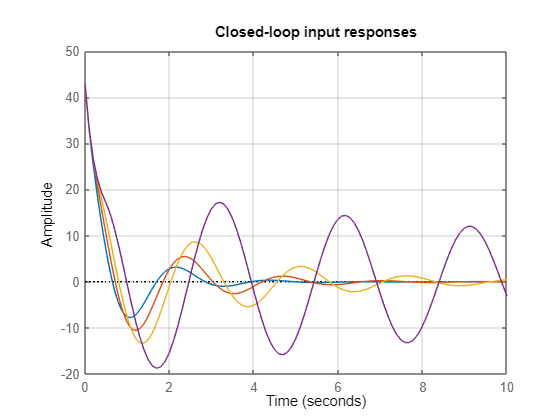


figure;clf
for k=1:ndelay
   step(Gcu{k},10);hold on; grid on
end
title('Closed-loop input responses')

disp('END of SECTION 2')

BELOW is SECTION 3: Changing design to take account of the delay


## 3. Design taking account of the delay using lag compensation

A simple lag design is used beginning  from approximately a 60 degree PM before the lag component is added; the same requirement is used irrespective of the delay. The offset requirement is 5%. We assume readers can use **lag_design_with_bode.mlx** to replicate the designs below if they are unsure of any steps.

- It is noticeable that the simple proportional design once the delay is added is much smaller.

- Also delay means the cross-over frequency is lower and in consequence the closed-loop responses are slower. 

- However, all 3 solutions obtain a similar PM as desired. The damping is not consistent because the relationship between PM and damping is only approximate.

- Try doing a lead or a lead-lag design on this system and making your own conclusions.

**NOTE**: The plots below have fixed domains to improve messaging. If you change the systems to selections of your own, you may need to change these domains.

disp('BELOW is SECTION 3: Changing design to take account of the delay')
G=tf(1,[1 5 8]);
delay=0.1;
Gd = G*tf(1,1,'iodelay',delay); % system with small delay
Gd2 = G*tf(1,1,'iodelay',delay*2); % system with larger delay
desiredPM = 60;
ess=0.05;

gamma=(1/(26*dcgain(G)))*((1/ess)-1);
M=26*tf([1,0.46],[1,0.46/gamma]); %LAG with no delay
gamma=(1/(17*dcgain(G)))*((1/ess)-1);
Md = 17*tf([1,0.33],[1,0.33/gamma]); % lag with delay of 0.1
gamma2=(1/(13.8*dcgain(G)))*((1/ess)-1);
Md2 = 13.8*tf([1,0.28],[1,0.28/gamma2]); % lag with delay of 0.2
figure;clf
step(feedback(G*M,1),feedback(Gd*Md,1),feedback(Gd2*Md2,1),10)
title('Closed-loop responses with lag compensation:  delay = [0, 0.1, 0.2]')



The change in cross-over frequency (intercept with 0DB) and reduction in high frequency gain is clear from the Bode diagrams below. **Note the low frequency gain and PM are not affected as the lag compensators are designed to achieve the same requirement here.**

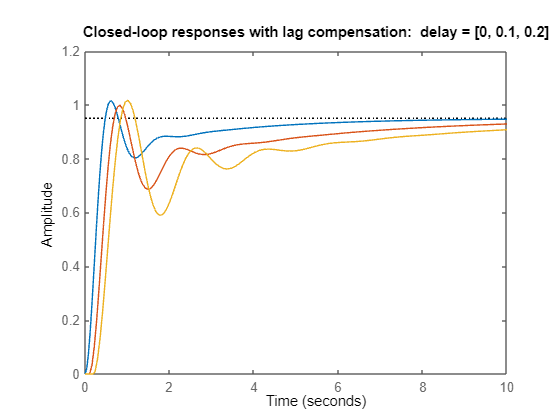

disp('Margins with delay = [0, 0.1, 0.2]')
[gm,pm] = margin(G*M);pm
[gm,pm] = margin(Gd*Md);pm
[gm,pm] = margin(Gd2*Md2);pm

disp(['Associated cross-over frequencies are: ',num2str([4.6, 3.3, 2.8])])
disp(['Associated proportional gains are: ',num2str([26, 17, 13.8])])

figure

Margins with delay = [0, 0.1, 0.2]


clf

pm = 55.9520

bode(G*M,Gd*Md,Gd2*Md2,{0.01,10});grid

pm = 54.8324

title('Lag compensation designed around the true delayed system')

pm = 54.2736

Associated cross-over frequencies are: 4.6         3.3         2.8


Associated proportional gains are: 26           17         13.8


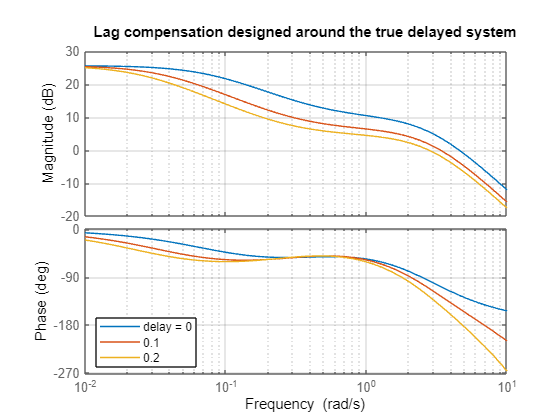

legend('delay = 0','0.1','0.2','location','southwest')